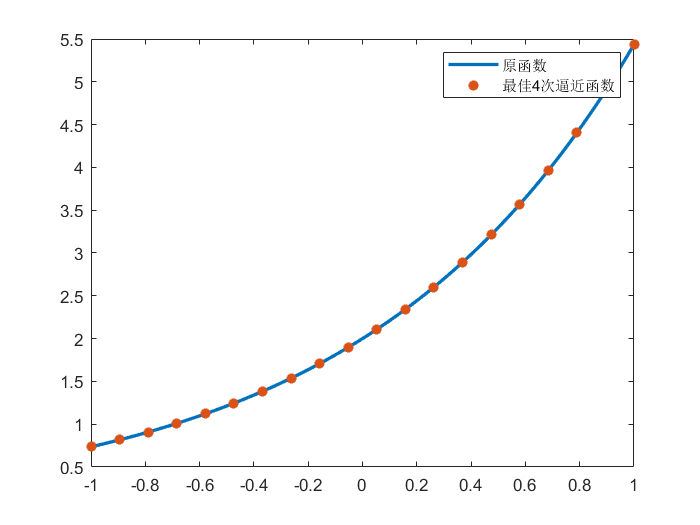

clc,clear,close all
syms x t

%------------设置------------%
f = 2*exp(x);   % 逼近函数
n = 4;          % 拟合次数
a = -1;         % 逼近区间
b = 1;          % 逼近区间 [a,b]

%-------------核心代码--------%  
% 算法公式： A*m=b 
% 其中 A 是希尔伯特矩阵，
% b 是 f(x) 与 基函数在0到1做定积分
% m 是基函数前的系数。
% S 逼近函数，是基函数前的系数与基函数做乘积再求和
% 注意：这一方法是在0到1上做函数逼近，因此，如果逼近区间不为[0,1]，需要做线性变换将区间变换到[0,1]

g = subs(f,x,(b-a)*t+a);    % 把逼近区间 [a,b] 变换到 [0,1]
A = hilb(n+1);              % 希尔伯特矩阵

d = zeros(n,1);
for i = 1:(n+1)
    g_i = g*t^(i-1);
    d(i) = int(g_i,t,0,1);
end
m = A\d;

S = 0;
for i = 1:(n+1)
    S = S + m(i)*t^(i-1);
end
S = subs(S,t,(x-a)/(b-a));
S = vpa(expand(S),4);

%----------结果输出---------%

% 作图
xx = a:0.01:b;
yy = vpa(subs(f,x,xx));
xx_1 = linspace(a,b,20);
yy_2 = vpa(subs(S,x,xx_1));
plot(xx,yy,xx_1,yy_2,'*','linewidth',2);
legend('原函数',['最佳',num2str(n),'次逼近函数'])

% 输出函数
disp(['最佳',num2str(n),'次逼近函数为'])

最佳4次逼近函数为


disp(S)

$$0.08719\,x^{4}+0.3523\,x^{3}+0.9987\,x^{2}+1.996\,x+2.0$$